## Import Geometry

clear
clc

Electrodep_pde =  createpde(1);
importGeometry(Electrodep_pde,'Electrodep Setup.stl')

ans =   DiscreteGeometry with properties:

       NumCells: 3
       NumFaces: 15
       NumEdges: 21
    NumVertices: 16
       Vertices: [16×3 double]


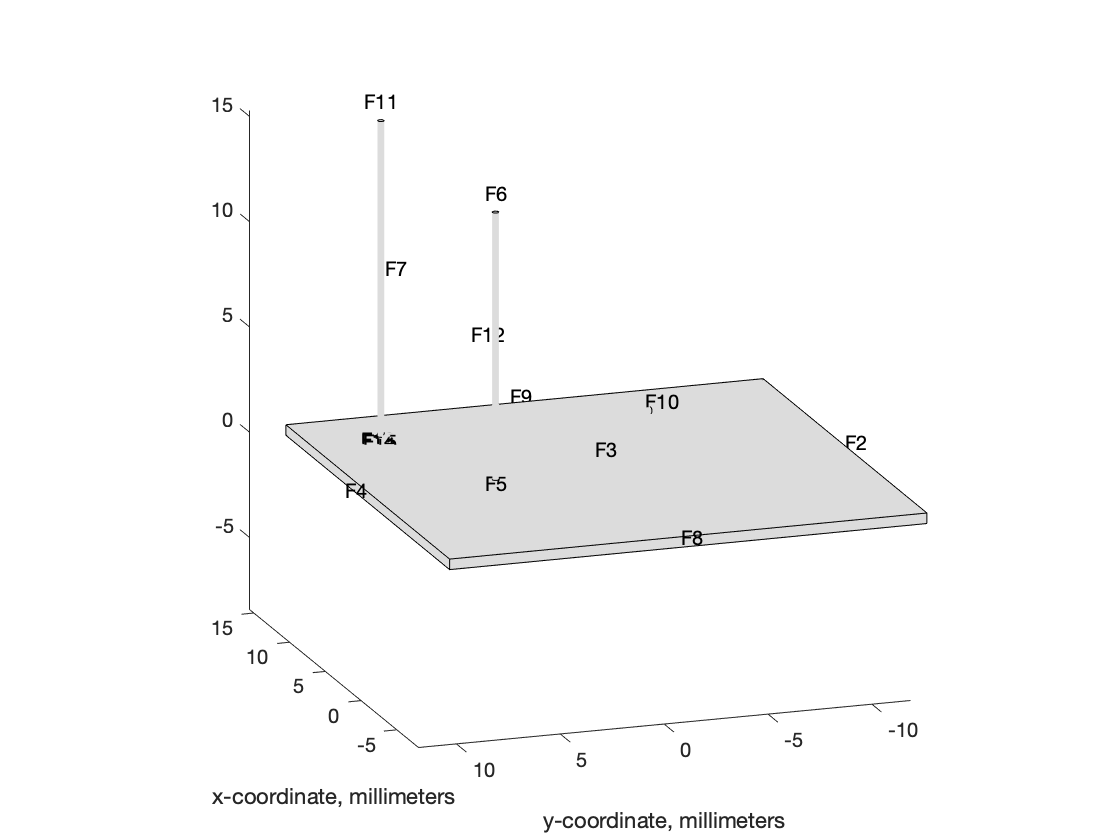


figure
pdegplot(Electrodep_pde,"FaceLabels","on")
xlabel('x-coordinate, millimeters')
ylabel('y-coordinate, millimeters')
axis([-40, 40,-40, 40, -40, 40])
axis square

## Specify PDE Coefficients

% PDE Coefficients for charge transfer
c = 1;
a = 0;
f = 0;

## Specify Boundary Conditions

% Ambient conditions
charge = 0;

% Permiability of medium coeff
perm = 0;

### ITO

% Faces with convective boundary conditions
ITO_Face = 3;
ITO_non_slides = [1 9 4 8 6]
% Apply conductive boundary condition
applyBoundaryCondition(Electrodep_pde,'neumann','Face', ...
    ITO_Face,'g',[-1;-1;-1])

applyBoundaryCondition(Electrodep_pde,'neumann','Face', ...
    ITO_Face,'g',[-1;-1;-1])

applyBoundaryCondition(Electrodep_pde,'dirichlet', 'Edge'...
    'Edge',[12,13,14,15,16,17,18, 19, 20, 21, 22,23],'u',V1);

### Working Electrode

applyBoundaryCondition(Electrodep_pde,'dirichlet', ...
                             'Edge',[1,2,3,4,5,6,7,8,9,10,11],'u',V1);

### Counter Electrode

applyBoundaryCondition(Electrodep_pde,'dirichlet', ...
                             'Edge',[24,25],'u',V0);


## Mesh

Electrodep_pde.generateMesh("Hmax",.5)

ans =   FEMesh with properties:

             Nodes: [3×34610 double]
          Elements: [10×16933 double]
    MaxElementSize: 0.5000
    MinElementSize: 0.2500
     MeshGradation: 1.5000
    GeometricOrder: 'quadratic'


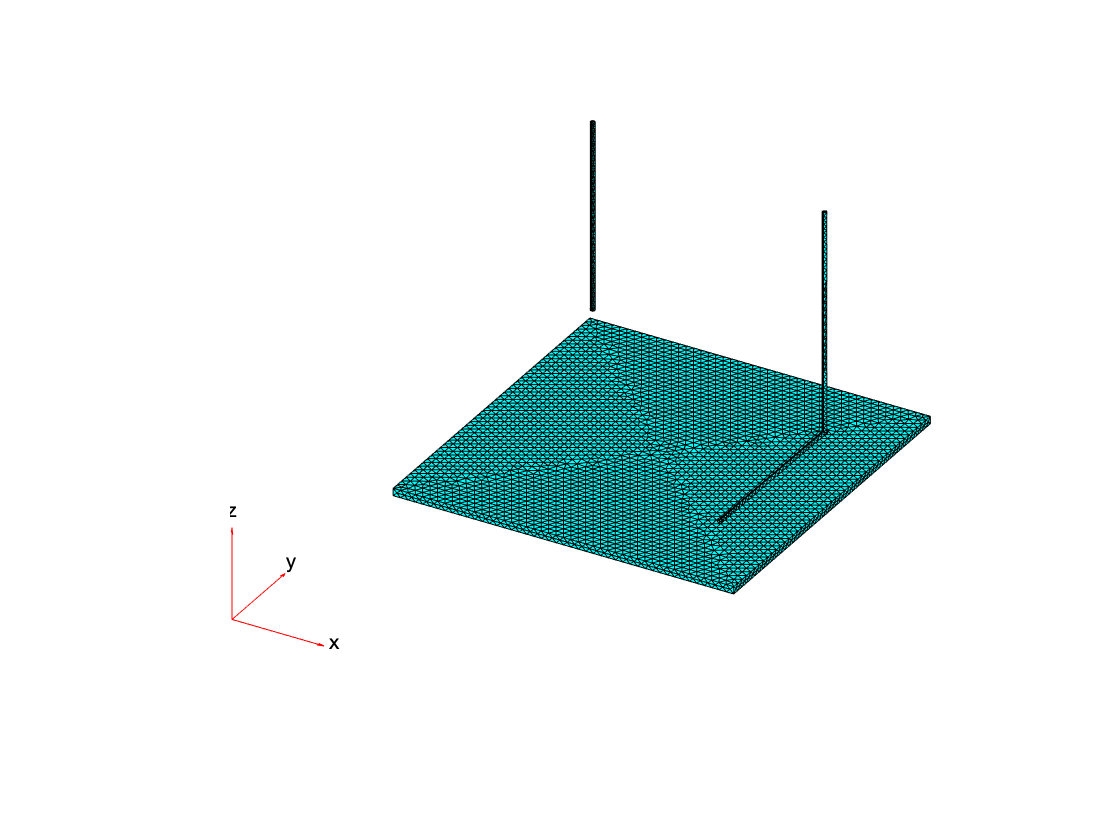

pdeplot3D(Electrodep_pde)

%Solve
results = assempde(Electrodep_pde,c,a,f);

Error using pde.FEMeshAssociation/getElementFaces
Face ID must be an integer in the range from 1 to the number of faces in the geometry.

Error in pde.internal.pde3DBCImpl/generateBoundaryFacetData (line 77)
            bcsi.elemFaces = msh.getElementFaces(bcsi.appRegionID);

Error in 

## Visualize

figure
pdeplot3D(Electrodep_pde,"ColorMapData",results);